Analyze data about one patient:

- Extract EEG data

- Apply Laplacian filter and compute PSD

- Choose discriminant features using Fisher score

- Train and save a classifier

- Evaluate performance with and without evidence accumulation

patients = find_patients('data');
patient = patients{1};

disp(strcat('Beginning data Analysis for patient: ', patient.name));

Beginning data Analysis for patient:ai6



info.fixation_code = 786;
info.cue_BH = 773;
info.cue_BF = 771;
info.cue_rest = 783;
info.feedback_code = 781;
info.offline_mode = 0;
info.online_mode = 1;

info.selected_frequencies = (4:2:48)';
info.channel_labels  = {'Fz', 'FC3', 'FC1', 'FCz', 'FC2', 'FC4', 'C3', 'C1', 'Cz', 'C2', 'C4', 'CP3', 'CP1', 'CPz', 'CP2', 'CP4'};
info.num_features = 3;

% Weights for channels and frequencies.
feature_weights = load('features_filter.mat').features_filter';

PSD_data = {};
for f = 1:length(patient.offline_files)
    % Raw EEG
    [s, h] = sload(patient.offline_files{f});
    
    % Apply Lap and compute PSD
    PSD_data{end+1} = psd_extraction(s, h);
    PSD_data{end}.modality = info.offline_mode;
end

[proc] |- Applying Laplacian
[proc] |- Computing spectrogram
[proc] |- Extracting and converting the events
[proc] |- Applying Laplacian
[proc] |- Computing spectrogram
[proc] |- Extracting and converting the events
[proc] |- Applying Laplacian
[proc] |- Computing spectrogram
[proc] |- Extracting and converting the events


for f = 1:length(patient.online_files)
    % Raw EEG
    [s, h] = sload(patient.online_files{f});
    
    % Apply Lap and compute PSD
    PSD_data{end+1} = psd_extraction(s, h);
    PSD_data{end}.modality = info.online_mode;
end

[proc] |- Applying Laplacian
[proc] |- Computing spectrogram
[proc] |- Extracting and converting the events
[proc] |- Applying Laplacian
[proc] |- Computing spectrogram
[proc] |- Extracting and converting the events
[proc] |- Applying Laplacian
[proc] |- Computing spectrogram
[proc] |- Extracting and converting the events
[proc] |- Applying Laplacian
[proc] |- Computing spectrogram
[proc] |- Extracting and converting the events
[proc] |- Applying Laplacian
[proc] |- Computing spectrogram
[proc] |- Extracting and converting the events
[proc] |- Applying Laplacian
[proc] |- Computing spectrogram
[proc] |- Extracting and converting the events



% We assume all frequencies to be the same for all data.
original_frequencies = PSD_data{1}.frequencies;

Concatenate data and create cue and trial vectors

[psd, events, run_k, mode_k] = concatenatePSD(PSD_data);
[cue_k, trial_k] = labelData(events, size(psd, 1));

% Extract the desired frequencies.
[psd, frequencies] = extractFrequencies(psd, original_frequencies, info.selected_frequencies);

% Apply log to psd
psd = log(psd);

Cache a few useful indices

offline_data = mode_k == info.offline_mode;
online_data = mode_k == info.online_mode;
bh_data = cue_k == info.cue_BH;
bf_data = cue_k == info.cue_BF;
bh_bf_data = bh_data | bf_data;

Extract features to train a classifier

classes = [info.cue_BF, info.cue_BH];
[selected_features, fisher_score_run] = psd2features( ...
    psd(offline_data, :, :), run_k(offline_data), cue_k(offline_data), ...
    classes, info.num_features, feature_weights ...
);

## compute mean fisher's score

mean_fisher_score = mean(fisher_score_run, 3);

## filter mean fisher's score

filtered_mean_Fisher = mean_fisher_score .* feature_weights;

## generate map of selected features

features_mask = zeros(size(mean_fisher_score));

for k = 1 : length(selected_features)
    feature_index = selected_features{k};
    features_mask(feature_index(1), feature_index(2)) = 1;
end

## Visualization Fisher score

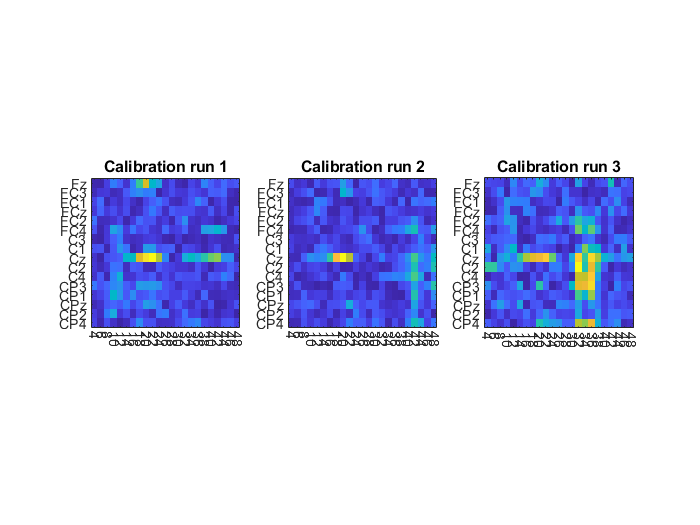

channelId  = 1:length(info.channel_labels);

NumRuns = length(patient.offline_files);
NumFreqs = length(frequencies);
NumChans = length(info.channel_labels);
classId    = [773 771];
classLb    = {'both hands', 'both feet'};
nclasses   = length(classId);
modalityId = [0 1];
modalityLb = {'offline', 'online'};
climits = [];
handles = nan(NumRuns, 1);
fig1 = figure;

for rId = 1:NumRuns
    subplot(1, 3, rId);
    imagesc(fisher_score_run(:, :, rId)');
    axis square;
    set(gca, 'XTick', 1:NumFreqs);
    set(gca, 'XTickLabel', frequencies);
    set(gca, 'YTick', 1:NumChans);
    set(gca, 'YTickLabel', info.channel_labels);
    xtickangle(-90);
    
    title(['Calibration run ' num2str(rId)]);
    
    climits = cat(2, climits, get(gca, 'CLim'));
    handles(rId) = gca;
end

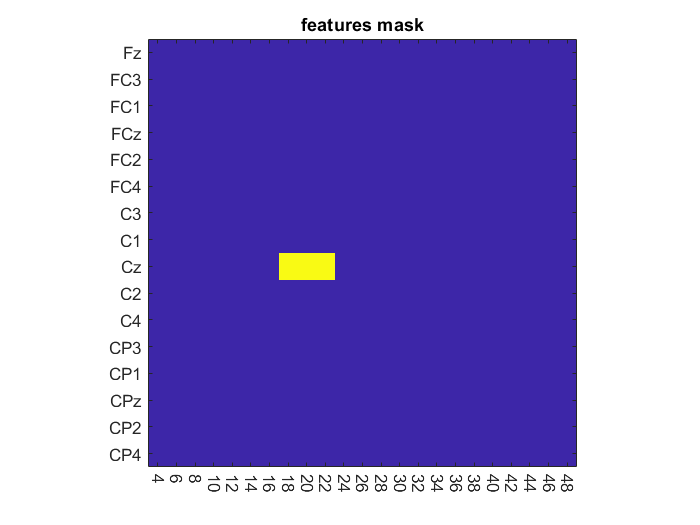


figure3=figure;
imagesc(features_mask');
axis square;
set(gca, 'XTick', 1:NumFreqs);
set(gca, 'XTickLabel', frequencies);
set(gca, 'YTick', 1:NumChans);
set(gca, 'YTickLabel', info.channel_labels);
xtickangle(-90);

title('features mask');

## train the classifier on offline data

X = extractFeatures(psd, selected_features);
training_set = X(offline_data & bh_bf_data, :);
training_labels = cue_k(offline_data & bh_bf_data);

test_set = X(online_data & bh_bf_data, :);
test_labels = cue_k(online_data & bh_bf_data);

## Choose a model using cross validation

model = train_binary_model(training_set, training_labels);

Model 1 obtained an average test accuracy of: 70.326162.
Model 2 obtained an average test accuracy of: 71.894518.
Model 3 obtained an average test accuracy of: 73.185288.


% Results on training set
predicted_labels = predict(model, training_set);
accuracy_tot = 100*sum(training_labels == predicted_labels)/length(training_labels)

accuracy_tot = 74.0736

accuracy_bh = 100*sum(predict(model, X(offline_data & bh_data, :)) == info.cue_BH)/sum(offline_data & bh_data)

accuracy_bh = 85.8690

accuracy_bf = 100*sum(predict(model, X(offline_data & bf_data, :)) == info.cue_BF)/sum(offline_data & bf_data)

accuracy_bf = 62.2814

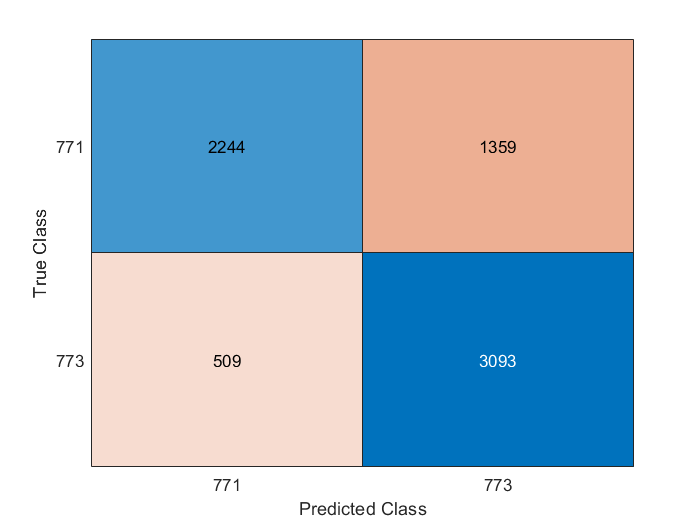

confusionchart(training_labels, predicted_labels);


% Results on test set
predicted_labels_test = predict(model, test_set);
accuracy_test = 100*sum(test_labels == predicted_labels_test)/length(test_labels)

accuracy_test = 70.8564

accuracy_bh_test = 100*sum(predict(model, X(online_data & bh_data, :)) == info.cue_BH)/sum(online_data & bh_data)

accuracy_bh_test = 74.3929

accuracy_bf_test = 100*sum(predict(model, X(online_data & bf_data, :)) == info.cue_BF)/sum(online_data & bf_data)

accuracy_bf_test = 66.6612

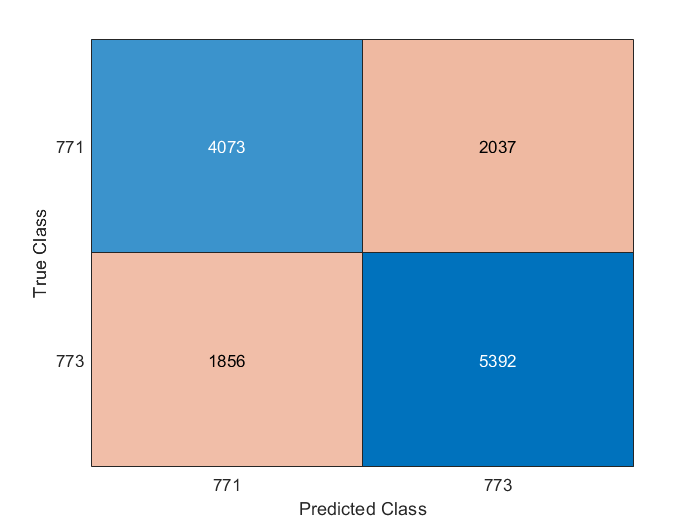

confusionchart(test_labels, predicted_labels_test);

# Evidence Accumulation

classify and accumulate evidence over the feedback period of online runs

the evidence accumulation is based on the posterior probability of class 771 both feet

## data

% online data
accumulation_data= X(online_data_index, :);
%predict on data
[a,post_probabilities] = predict(model, accumulation_data);

num_samples = length(accumulation_data);
num_classes = length(classes);
% reset accumulation to the base probability of this class = 1/num_classes
reset_accumulation = 1./num_classes;
% vector of start of feedback for each trial
feedback_starts = EVENT.POS(EVENT.TYP==code.feedback & EVENT.MOD==modality.online);
%shift to manage only data in online part
feedback_starts = feedback_starts - sum(offline_data_index);

## Exponential smoothing

% coefficient that determines how the system respond to the new sample (high-> conservative, low->responsive)
alpha_ex = 0.9;

% compute accumulator
accumulator_ex = exponential_smoothing(post_probabilities, num_classes, feedback_starts, alpha_ex);

## Dynamic smoothing

% coefficient that determines how the system respond to the new sample (high-> conservative, low->responsive)
alpha_dyn = 0.5;
beta = 0.11;
conservative_amp = 0.1;
w = 0.3;
free_force_function = @(x) f_free(x,conservative_amp,w);
bmi_force_function = @(x) f_bmi_sin(x);

% compute accumulator
accumulator_dyn = dynamic_smoothing(post_probabilities, num_classes, feedback_starts, alpha_dyn, beta, free_force_function, bmi_force_function);

## moving average

alpha_mov = 0.4;
% compute accumulator
accumulator_mov = mov_avg_smoothing(post_probabilities, num_classes, feedback_starts, alpha_mov);

# EVIDENCE ACCUMULATION PERFORMANCE

## data

% scale down trial labels index to online data
trial_label_scaled = trial_labels(online_data_index);
% index for the feedback part of the data used in accumulation
feedback_index = getLabelsForEventType(EVENT, code.feedback, num_windows);
% scale down feedback index to online data
feedback_index_scaled = feedback_index(online_data_index);
% vector of true class for the trial
true_class = EVENT.TYP((EVENT.TYP==code.cue_BF | EVENT.TYP==code.cue_BH | EVENT.TYP==code.cue_rest) & EVENT.MOD==modality.online);
up_threshold_ex = 0.7;
down_threshold_ex = 0.3;
up_threshold_dyn = 0.77;
down_threshold_dyn = 0.3;
up_threshold_mov = 0.7;
down_threshold_mov = 0.3;
[perf_active_ex, perf_resting_ex, perf_active_rej_ex] = evaluate_accumulation(up_threshold_ex, down_threshold_ex, true_class, accumulator_ex, feedback_index_scaled, trial_label_scaled)

perf_active_ex = 76.6667

perf_resting_ex = NaN

perf_active_rej_ex = 81.4159

[perf_active_dyn, perf_resting_dyn, perf_active_rej_dyn] = evaluate_accumulation(up_threshold_dyn, down_threshold_dyn, true_class, accumulator_dyn, feedback_index_scaled, trial_label_scaled)

perf_active_dyn = 46.6667

perf_resting_dyn = NaN

perf_active_rej_dyn = 78.8732

[perf_active_mov, perf_resting_mov, perf_active_rej_mov] = evaluate_accumulation(up_threshold_mov, down_threshold_mov, true_class, accumulator_mov, feedback_index_scaled, trial_label_scaled)

perf_active_mov = 49.1667

perf_resting_mov = NaN

perf_active_rej_mov = 70.2381

## plot results of evidence accumulation

% fig1 = figure;
%
% CueClasses    = [771 783 773];
% LbClasses     = {'both feet', 'rest', 'both hands'};
% ValueClasses  = [1 0.5 0];
% Threshold     = 0.7;
%
% SelTrial = 50;

% Trial 15: good rest
% Trial 80: bad rest
% Trial 55: good both hands
% % Trial 58: good both feet
%
% cindex = Tk == SelTrial;
% [~, ClassIdx] = ismember(unique(Ck(cindex)), CueClasses);
%
% GreyColor = [150 150 150]/255;
% LineColors = {'b', 'g', 'r'};
%
% hold on;
% % Plotting raw probabilities
% plot(pp(cindex, 1), 'o', 'Color', GreyColor);
%
% % Plotting accumulutated evidence
% plot(ipp(cindex), 'k', 'LineWidth', 2);
%
% % Plotting actual target class
% yline(ValueClasses(ClassIdx), LineColors{ClassIdx}, 'LineWidth', 5);
%
% % Plotting 0.5 line
% yline(0.5, '--k');
%
% % Plotting thresholds
% yline(Threshold, 'k', 'Th_{1}');
% yline(1-Threshold, 'k', 'Th_{2}');
% hold off;
%
% grid on;
% ylim([0 1]);
% xlim([1 sum(cindex)]);
% legend('raw prob', 'integrated prob');
% ylabel('probability/control')
% xlabel('sample');
% title(['Trial ' num2str(SelTrial) '/' num2str(NumTrials) ' - Class ' LbClasses{ClassIdx} ' (' num2str(CueClasses(ClassIdx)) ')']);